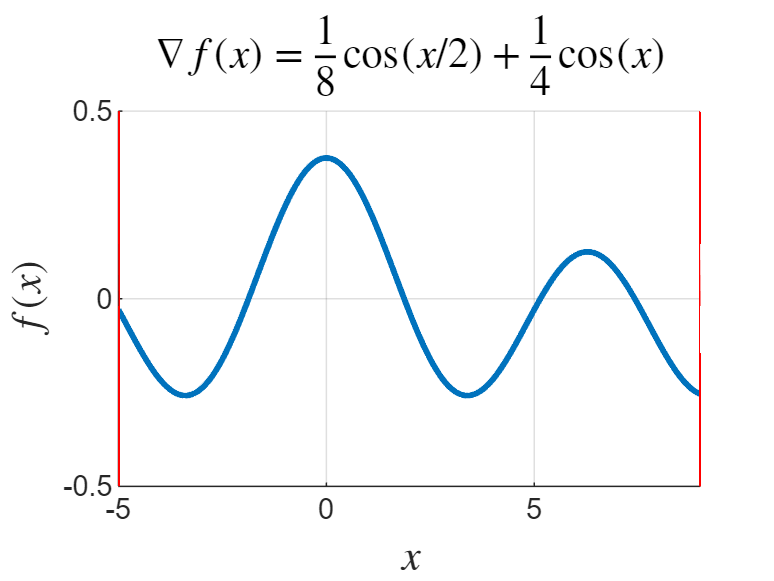

clear a7  b7; clc; close all;
clf; hold off;
syms x

f = @(x) (sin(x) + sin(x/2))/4;
df = matlabFunction(diff(f, x));

t = -5:0.01:9;
a0 = -5; b0 = 9;
ymin = -0.5 ; ymax = 0.5 ;

[a7, b7] = bisection_search(df, a0, b0, 5e-2);
rowp = size(a7,1);

figure(1);
%set(gcf,'Position',[0 0 900 400])
% Plot initial function 
axis([-5, 9, ymin, ymax]); grid;
hold on
    plot(t, df(t), 'LineWidth',2); 
    title("$\nabla f(x) = \frac{1}{8}\cos(x/2) + \frac{1}{4}\cos(x)$", ...
        'Interpreter','latex','FontSize',14);
    xlabel("$x$", 'Interpreter','latex','FontSize',14);
    ylabel("$f(x)$",'Interpreter','latex','FontSize',14);
    % The boundary is very narrow
    plot([a0 a0], [ymin, ymax], 'LineWidth',1,'Color','red'); 
    plot([b0 b0], [ymin, ymax], 'LineWidth',1, 'Color','red');
hold off

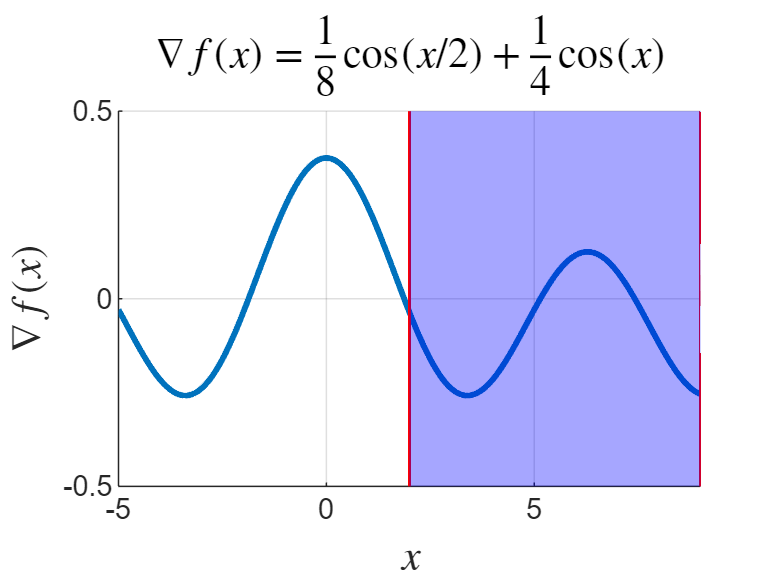

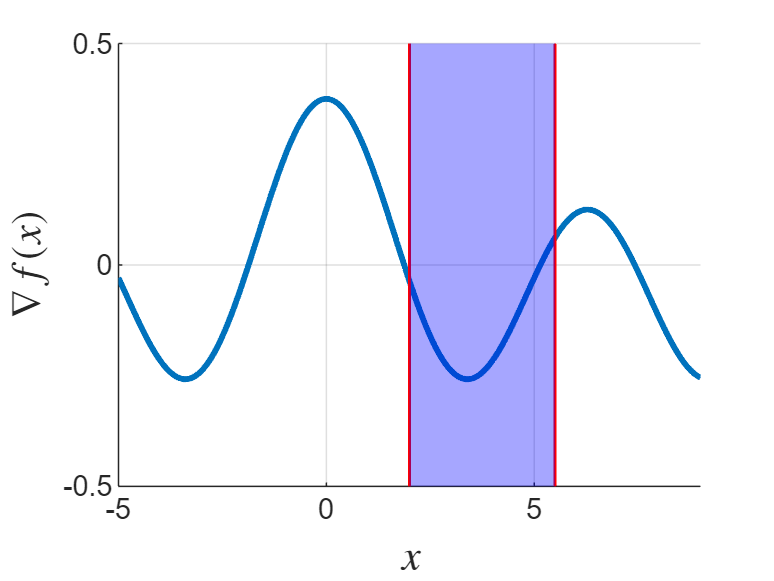

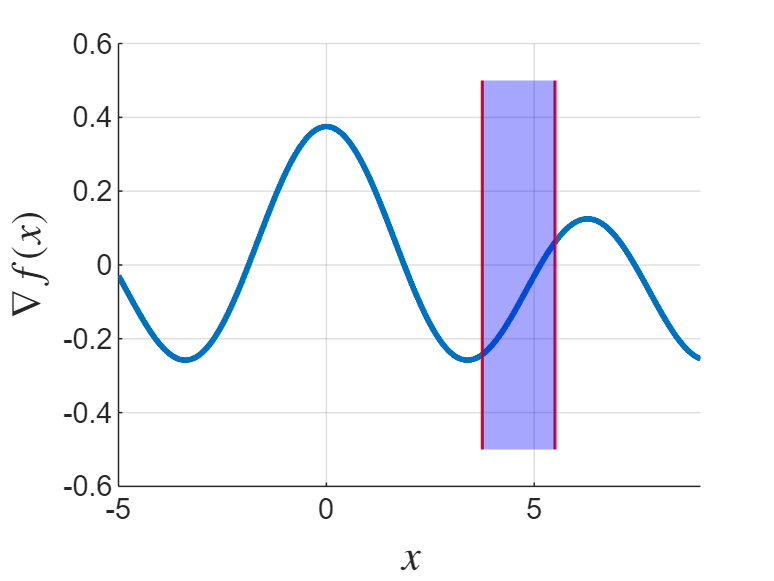

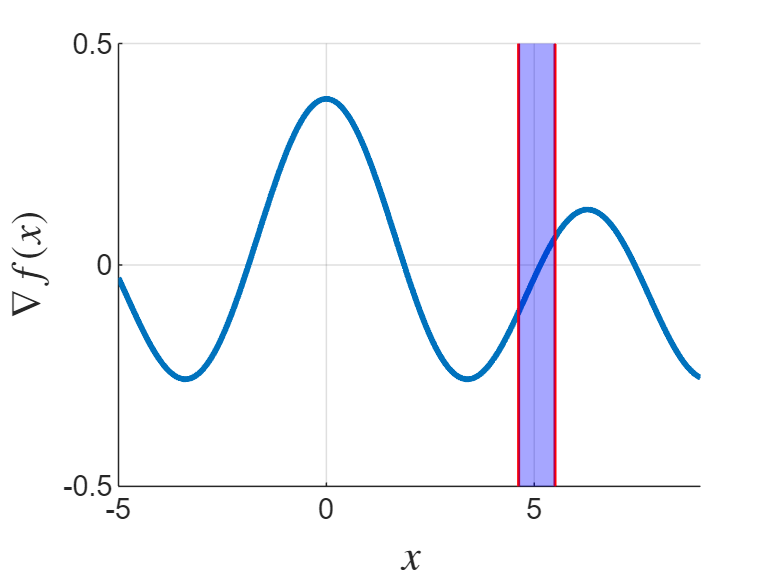

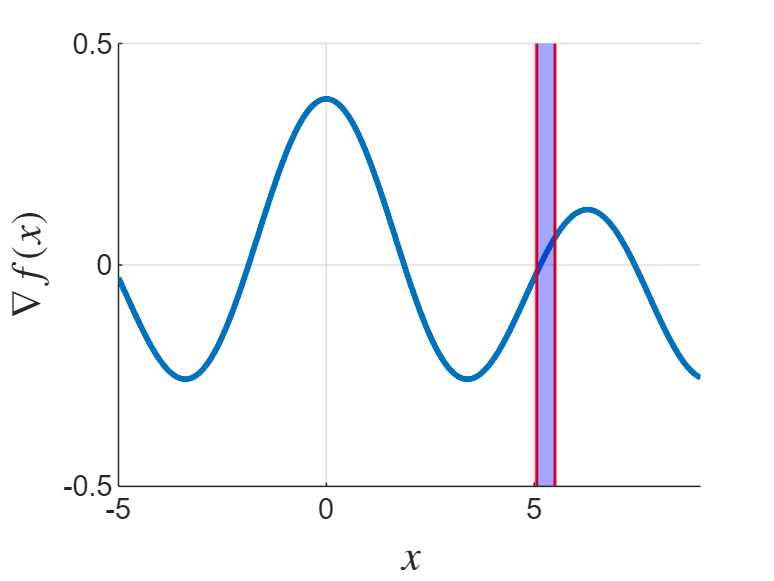

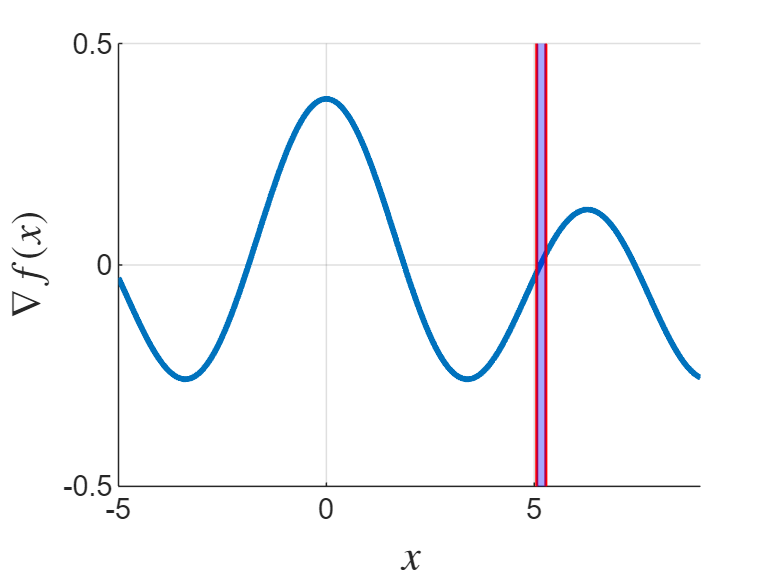

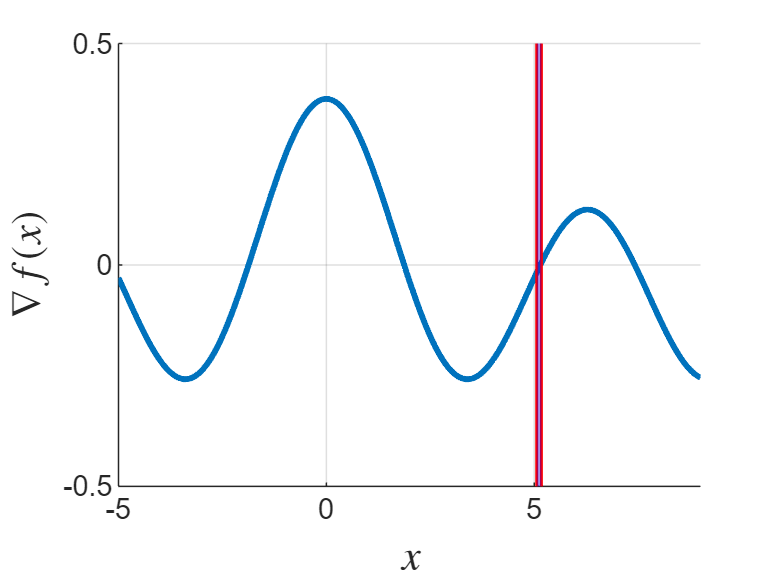

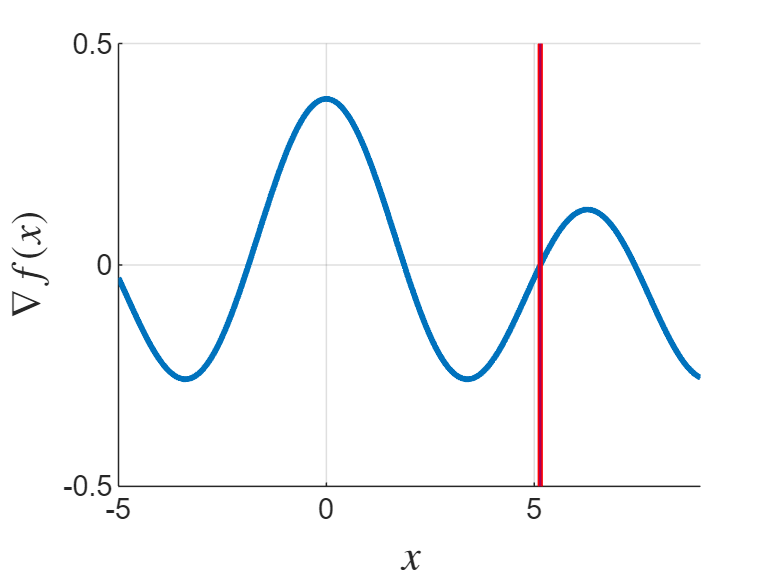


% Plot the bisection steps.
figure(2)
title("$\nabla f(x) = \frac{1}{8}\cos(x/2) + \frac{1}{4}\cos(x)$", ...
        'Interpreter','latex','FontSize',14);
for i = 1: rowp
    %subplot(rowp, 1,i)
    figure(i+1)
    axis([-5, 9, ymin, ymax]); grid;
    hold on
    plot(t, df(t), 'LineWidth',2); 
    xlabel("$x$", 'Interpreter','latex','FontSize',14);
    ylabel("$\nabla f(x)$",'Interpreter','latex','FontSize',14);
    % The boundary is very narrow
    plot([a7(i) a7(i)], [ymin, ymax], 'LineWidth',1,'Color','red'); 
    plot([b7(i) b7(i)], [ymin, ymax], 'LineWidth',1, 'Color','red');

    pgon1 = polyshape([ a7(i) a7(i) b7(i) b7(i) ], ...
        [ ymin, ymax, ymax, ymin ], 'Simplify',false);  
    plot(intersect(pgon1,pgon1),'EdgeColor','none','FaceColor','b')


    hold off
end

drawnow;
a7

a7 =     2.0000
    2.0000
    3.7500
    4.6250
    5.0625
    5.0625
    5.0625
    5.1172
    5.1445


b7

b7 =     9.0000
    5.5000
    5.5000
    5.5000
    5.5000
    5.2812
    5.1719
    5.1719
    5.1719


sol = (a7(end) + b7(end))/2 

sol = 5.1582